%create a PDE model
numberOfPDE = 1; %number of dependent variables
model = createpde(numberOfPDE);

%specify the variables that define the problem
g = @scatterg; %Geometry specification function
%scatterg is a predefined geometry
%we can make other geometries and use them 
%in the code this way from other files
%coefficients and inhomogeneous term
k = 60;
c = 1;
a = -k^2;
f = 0

f = 0

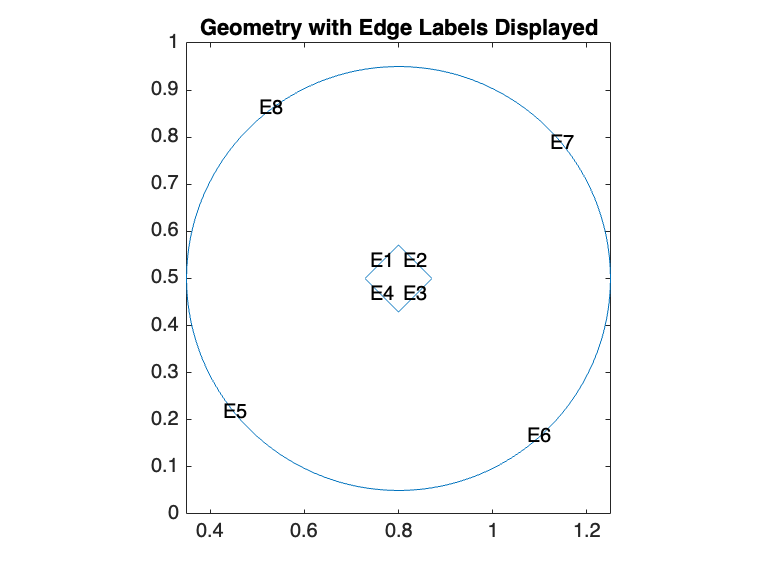


%convert the geometry and append it to the model
geometryFromEdges(model,g);

%plot geometry
figure;
pdegplot(model,"EdgeLabels","on"); %!don't forget the g in the function!!!
axis equal
title("Geometry with Edge Labels Displayed")
ylim([0,1])

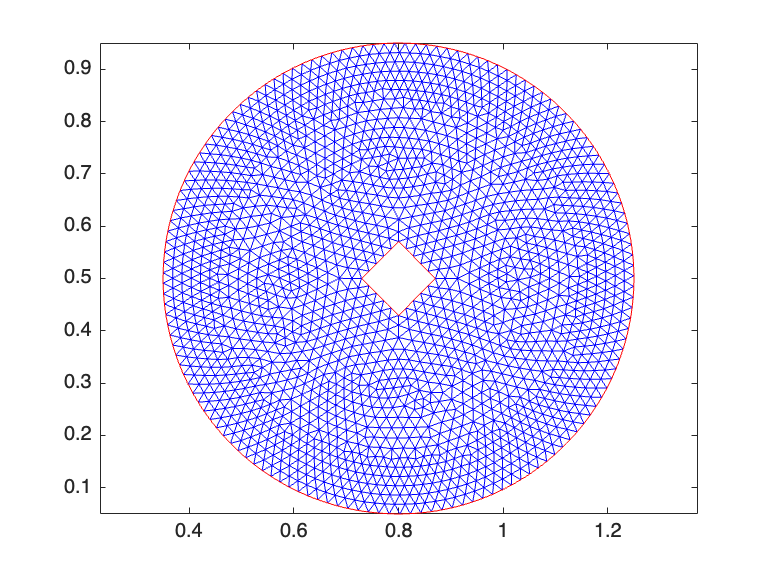


%apply boundary conditions
bOuter = applyBoundaryCondition(model, "neumann", "Edge",(5:8), ...
    "g",0,"q",-60i);
innerBCFunc = @(loc,state)-exp(-1i*k*loc.x);
bInner = applyBoundaryCondition(model,"dirichlet","Edge",(1:4), ...
    "u",innerBCFunc);

%specify the coefficients of the PDE
specifyCoefficients(model,"m",0,"d",0,"c",c,"a",a,"f",f);

%generate a mesh
%general command would be generateMesh(model)
%extra parameters are used to refine the mesh
generateMesh(model, "Hmax",0.02);
figure
pdemesh(model);
axis equal

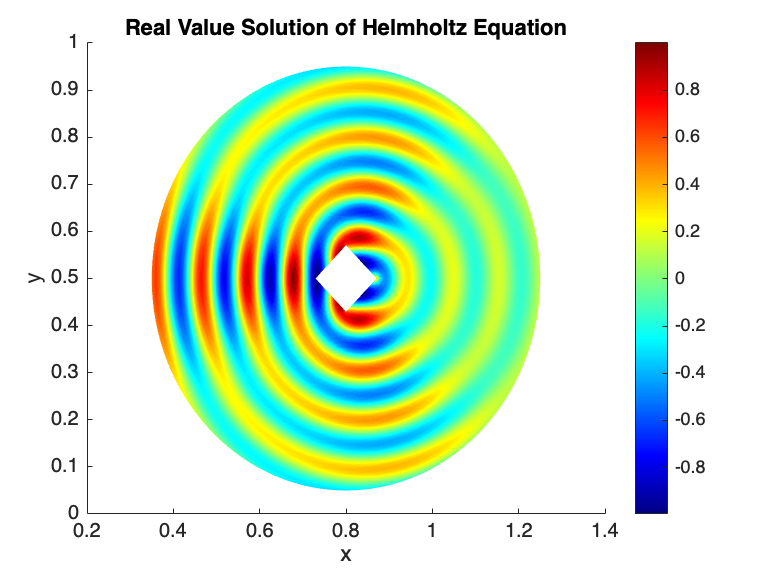


%Solve for the complex amplitude.
%real part of vector u stores an approximation to a real value solution of
%the Helmholtz equation.
result = solvepde(model);
u = result.NodalSolution;

%for time-dependent solution, need to include a tlist
%which is a range of time the solution should take place over

%Plot the solution
figure
pdeplot(model, "XYData",real(u),"Mesh","off");
colormap(jet)
xlabel("x")
ylabel("y")
title("Real Value Solution of Helmholtz Equation")

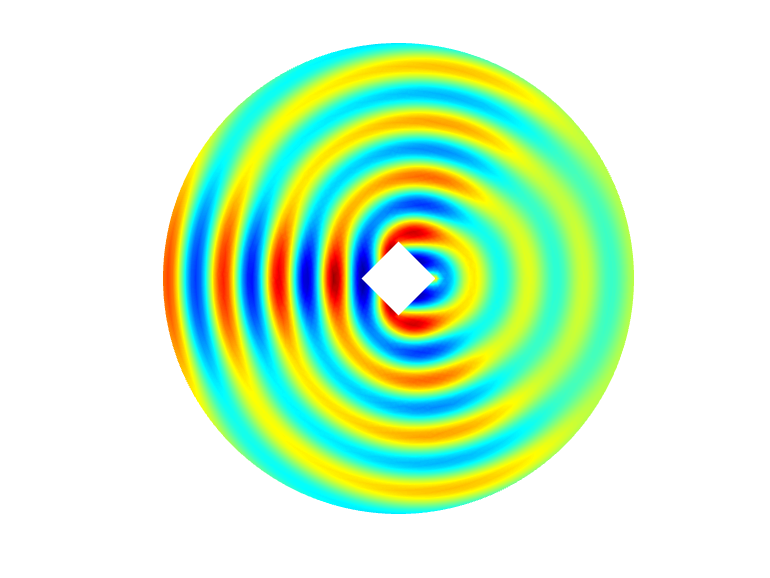


%create an animation showing the corresponding solution to the
%time-dependent wave equation
figure
m = 10;
maxu = max(abs(u));
for j = 1:m
    uu = real(exp(-j*2*pi/m*sqrt(-1))*u);
    pdeplot(model,"XYData",uu,"ColorBar","off","Mesh","off");
    colormap(jet)
    caxis([-maxu maxu]);
    axis tight
    ax = gca;
    ax.DataAspectRatio = [1 1 1];
    axis off
    F(j) = getframe;
end

movie(F)
